## MATLAB Live scripts demonstating aspects of Optimal Interpolation.

#### The methodology follows Chapter 4, *The spatial analysis of data fields,* in: Thompson, R.E. and W. J. Emery (2014) "Data analysis methods in physical oceanography," Elsevier, [https://doi.org/10.1016/C2010-0-66362-0](https://doi.org/10.1016/C2010-0-66362-0)

#### John L. Wilkin - jwilkin@rutgers.edu

## Exercise 2: SST patterns of Tropical Instability Waves in the eastern Equatorial Pacific - Pseudo-observations generated by sampling output from the NOAA RTOFS ocean model 

For an overview of the dynamics of Tropical Instability Waves, see: Willett, C.S., Leben, R.R. and Lavín, M.F., 2006. Eddies and tropical instability waves in the eastern tropical Pacific: A review. *Progress in Oceanography*, *69*(2-4), pp.218-238. [https://doi.org/10.1016/j.pocean.2006.03.010](https://doi.org/10.1016/j.pocean.2006.03.010) 

### This live script allows the user to vary the sampling resolution and the magnitude of the simulated observational error to explore the sensitivity of the interpolated field in comparison to the "truth".

%

#### Load example data set and subsample spatially to create a set of pseudo observations

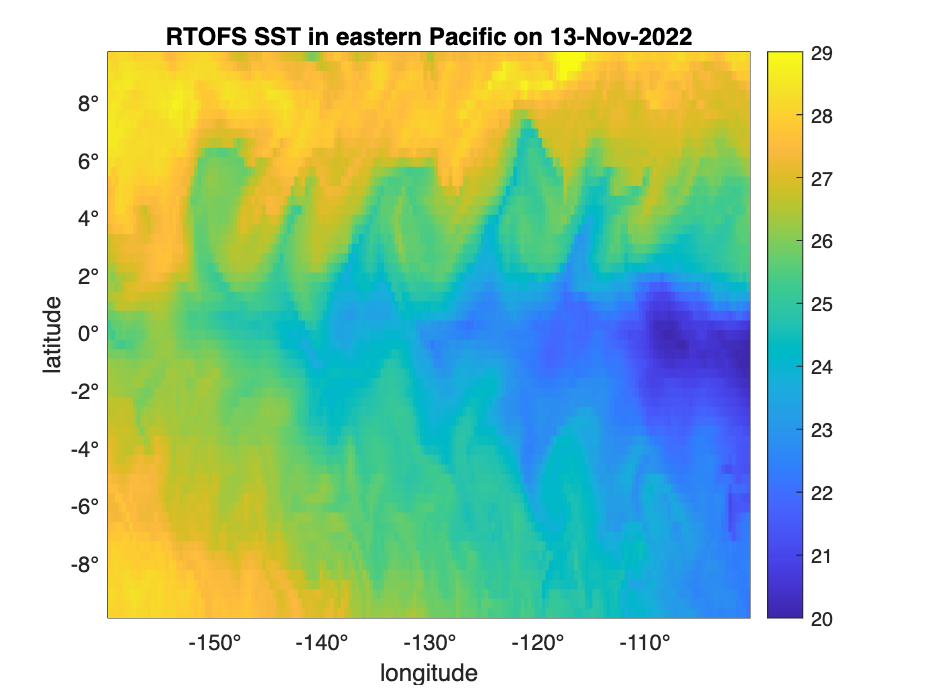

% Pseudo data are generated using example outputs from the NOAA RTOFS ocean model 
% in the equatorial Pacific showing Tropical Instability Waves
load oi_rtofs_data.mat
DATAF = rt.sst;
[LON,LAT] = ndgrid(rt.lon,rt.lat);

% Plot the full data set again for comparison
pcolor(LON,LAT,DATAF)
shading flat
caxis([20 29])
colorbar
title("RTOFS SST in eastern Pacific on "+rt.date)
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')


frac = 0.1;
disp(int2str(100*frac)+"% of the data are retained as pseudo observations")

10% of the data are retained as pseudo observations



% Get set of unique random integers spanning the length of the full data set 
% and use this to subsample/decimate the true field
N = numel(DATAF);
ss = randperm(N,round(frac*N));
data = DATAF(ss);
disp("OI will be performed using "+int2str(numel(ss))+" observations")

OI will be performed using 1080 observations



% Get corresponding coordinates of the sample set
% [LON,LAT] = ndgrid(rt.lon,rt.lat);
x = LON(ss);
y = LAT(ss);

#### Add random noise to simulate observational error

e = 0.2; % degrees C
disp("The pseudo data simulated observation error is "+num2str(e)+" degC")

The pseudo data simulated observation error is 0.2 degC


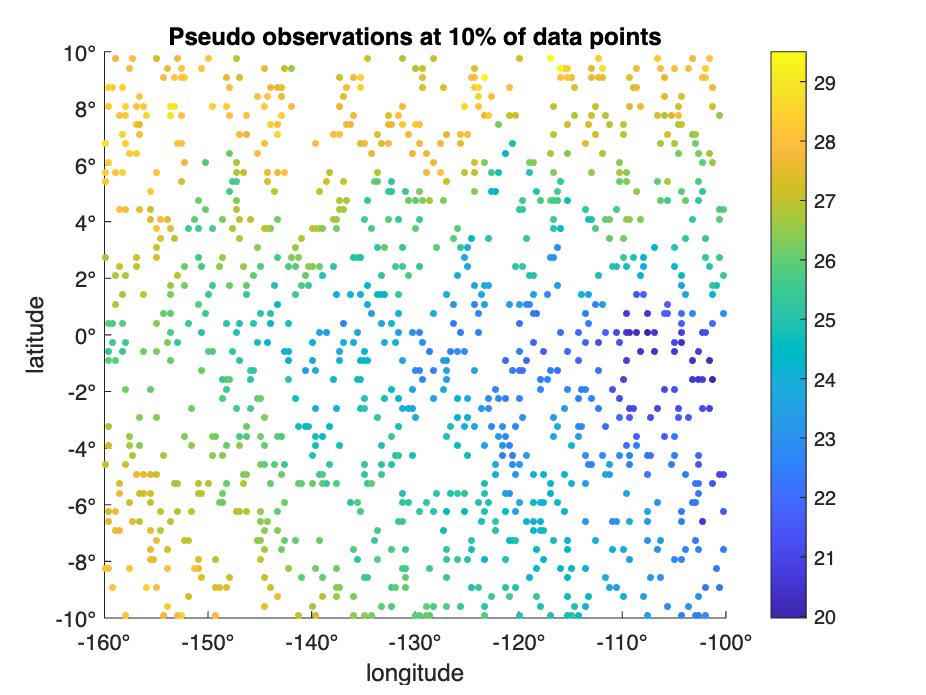

data = data + e*randn(size(data));

% Force column vectors
x = x(:);
y = y(:);
data = data(:);

% Plot the data
scatter(x,y,10,data,'o','filled')
colorbar
title("Pseudo observations at "+int2str(round(frac*100))+...
  "% of data points")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

#### Prepare for Optimal Interpolation

% save the mean of the data for later
datam = mean(data);

% compute data anomaly from the mean - optimal interpolation works on the anomaly
dataa = data - datam;

% Create matrices that repeat the observation coordinates: columns 
% of x, and rows of y. X-X' and Y-Y' will be all possible distance 
% combinations between pairs of points
Xobs = repmat(x,[1 length(y)]);
Yobs = repmat(y',[length(x) 1]);
Rdd = sqrt((Xobs-Xobs').^2+(Yobs-Yobs').^2);

% The live script oi_cov_estimation.mlx was previously used to analyze these 
% data and determine that the Le Traon covariance function 
% f = ssq*exp(-r/a)*(1+r/a+((r/a)^2)/6-((r/a)^3)/6 represented well the
% covariance of a sample of these data, where ssq is the signal variance at
% zero lag and the length scale is parameter "a" in degress lon/lat.

a = 0.9;
disp("The covariance length scale (in degree lon/lat) is "+num2str(a))

The covariance length scale (in degree lon/lat) is 0.9



ssq = 0.17;
disp("The signal standard deviation squared at zero lag is "+num2str(ssq))

The signal standard deviation squared at zero lag is 0.17



% In OI, the ratio of error variance to signal variance, e^2/ssq, is added to the 
% diagonal of the data-data covariance matrix. If, as user, you wish only to set 
% this ratio and not explicit values of e and ssq separately, then set ssq = 1 here 
% and above set e^2 to be the assumed normalized observation error variance.

disp("Using Le Troan function for covariance "+newline...
  +" f = a0*exp(-r/a)*(1+r/a+(r^2)/6-(r^3)/6)"+newline...
  +" with length scale"+newline...
  +" a = "+num2str(a)+" deg lon/lat or ~80 km"+newline...
  +" and estimated signal variance at zero lag (r=0) of "+num2str(ssq,2))

Using Le Troan function for covariance 
 f = a0*exp(-r/a)*(1+r/a+(r^2)/6-(r^3)/6)
 with length scale
 a = 0.9 deg lon/lat or ~80 km
 and estimated signal variance at zero lag (r=0) of 0.17



disp("A noise to signal variance ratio of "+num2str(e^2/ssq,3)...
  +" will be added to the diagonal of the data-data covariance matrix")

A noise to signal variance ratio of 0.235 will be added to the diagonal of the data-data covariance matrix


#### Build the data-data covariance matrix 

% The data-data covariance matrix is modeled based on the chosen continuous 
% covariance function and the distance between observation points. Since
% the covariance function is isotropic, i.e. the same in all directions, 
% we can evaluate the matrix simply using the separation distance of every 
% data point from every other point in Rdd computed above. Note, to keep
% this code compact, no adjustments are made for spherical geometry are made 
% to distances expressed in lon/at. Strictly speaking, the covariance function 
% should be expressed in true geographic distance, but we are at the equator and 
% the effects are small. Arguably, there are situations when covariance scales are
% anisotropic and it might be best to actually select different scales in
% lon and lat.

% The normalised (C=1 at r=0, instead of ssq) fitted data covariance matrix
% is then
Rddona = Rdd/a;
Cdd0 =  exp(-Rddona).*(1+Rddona+(Rddona.^2)/6-(Rddona.^3)/6);

% Add error variance nomalized by signal variance along the diagonal
lambda = e^2/ssq;
Cddf = Cdd0 + lambda*eye(size(Cdd0));

#### Build the model-data covariance function

% Here, "model" is the mapped solution on some other set of target
% coordinates. Typically the target coordinates are a regular grid, which 
% can be at any resolution.

% In this exercise, we map to the original RTOFS grid to facilitate easy 
% comparison to the true field and optimally interpolated field (from the 
% subsampled data with added observation noise). 

% Get distances between every grid point and every data point
Xgrid = repmat(LON(:),[1 numel(y)]);
Xdata = repmat(x(:),[1 numel(LAT)]);
Ygrid = repmat(LAT(:)',[length(x) 1]);
Ydata = repmat(y',[numel(LAT) 1]);
Rmd = sqrt((Xgrid-Xdata').^2+(Ygrid'-Ydata).^2);

% Evaluate the normalized covariance using the chosen covariance function
Rmdona = Rmd/a;
Cmd =  exp(-Rmdona).*(1+Rmdona+(Rmdona.^2)/6-(Rmdona.^3)/6);

#### Perform the Optimal Interpolation 

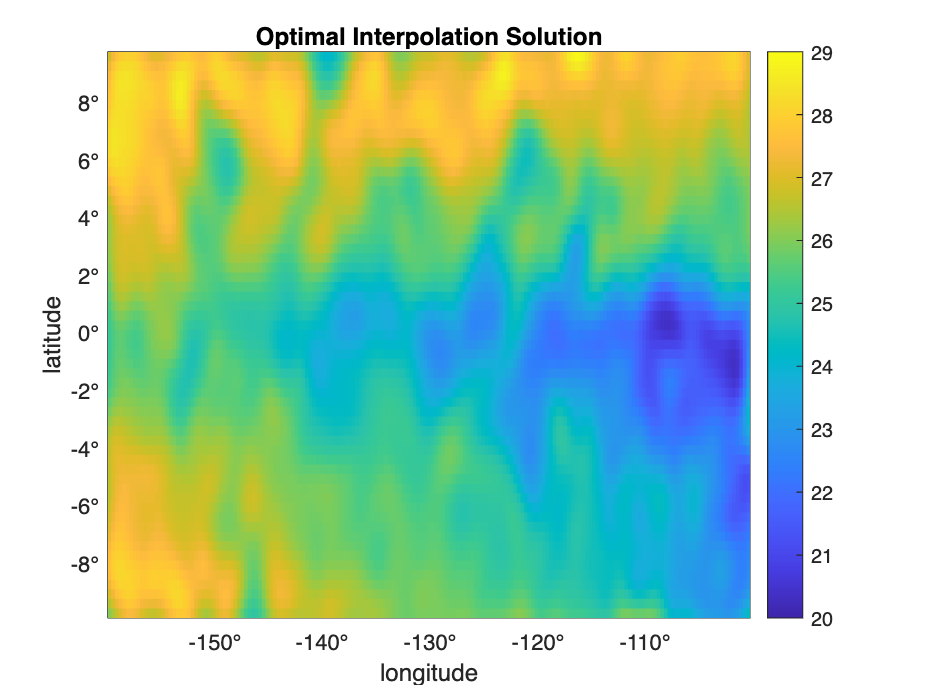

% Formally, OI evaluates Cmd*inv(Cdd)*data, but it is faster to use a
% Matrix Left Divide. See >> help mldivide 

Da = Cmd*(Cddf\dataa);
Da = reshape(Da,size(LON));
DOI = datam + Da; % must add back the mean value

% Plot the interpolated field
pcolor(LON,LAT,DOI)
shading flat
caxis([20 29])
colorbar
title("Optimal Interpolation Solution")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

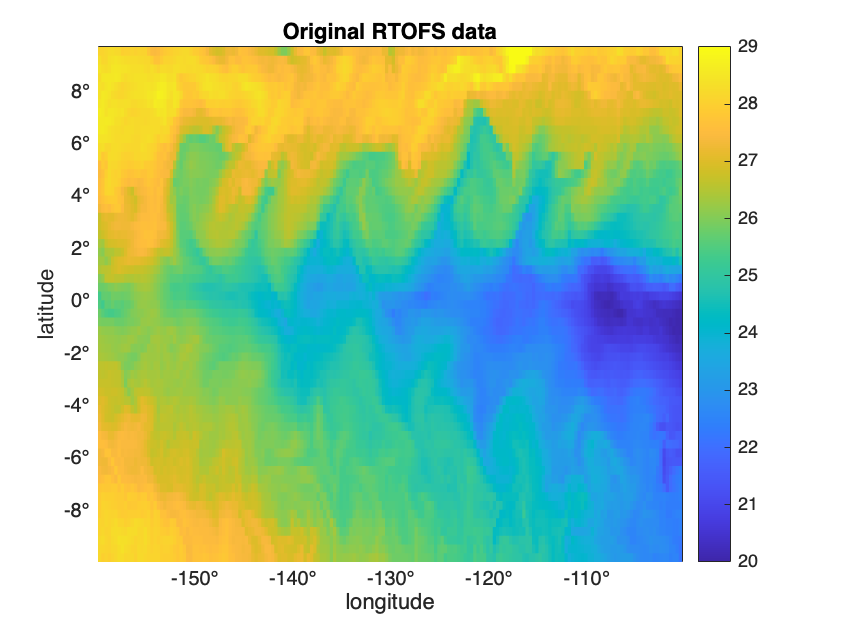


% Plot the full data set again for comparison
pcolor(LON,LAT,DATAF)
shading flat
caxis([20 29])
colorbar
title("Original RTOFS data")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')


% Plot the difference of the interpolated and original fields
pcolor(LON,LAT,DOI-DATAF)
shading flat
caxis([-5 5])
colorbar
title("Optimal interpolation minus original RTOFS data"+newline...
  +"and locations of the pseudo-data")
hold on
han = scatter(x,y,20,'w','o','MarkerEdgeColor','w');
han.MarkerEdgeColor = 0.9*[1 1 1];
hold off
disp("Notice that differences between the mapped and true fields"+newline...
  +"are greatest where the observations are sparse")

Notice that differences between the mapped and true fields
are greatest where the observations are sparse


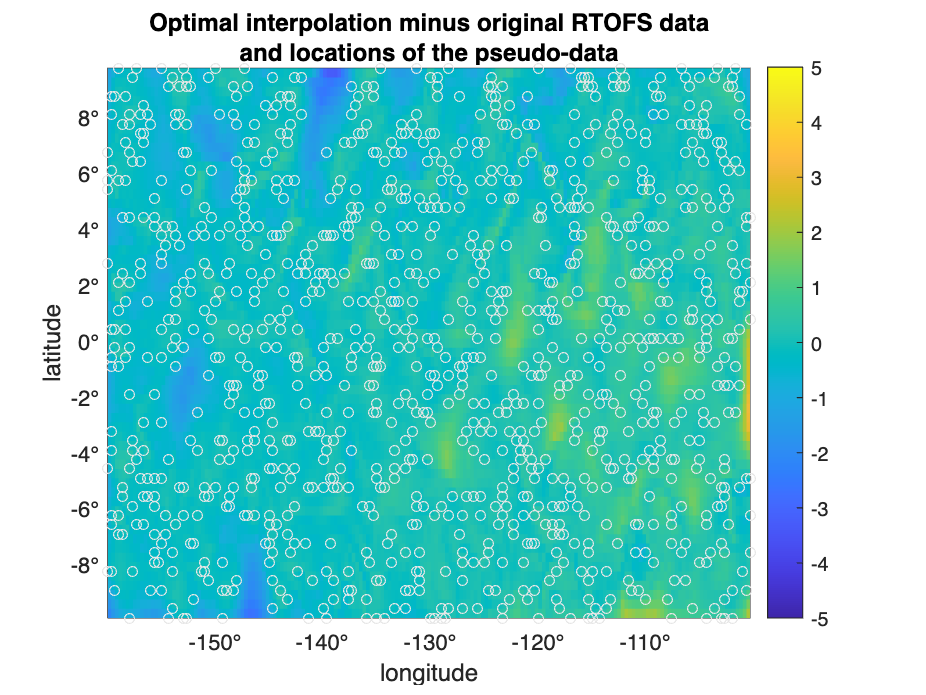

xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

#### Examine residuals of the interpolated noisy data

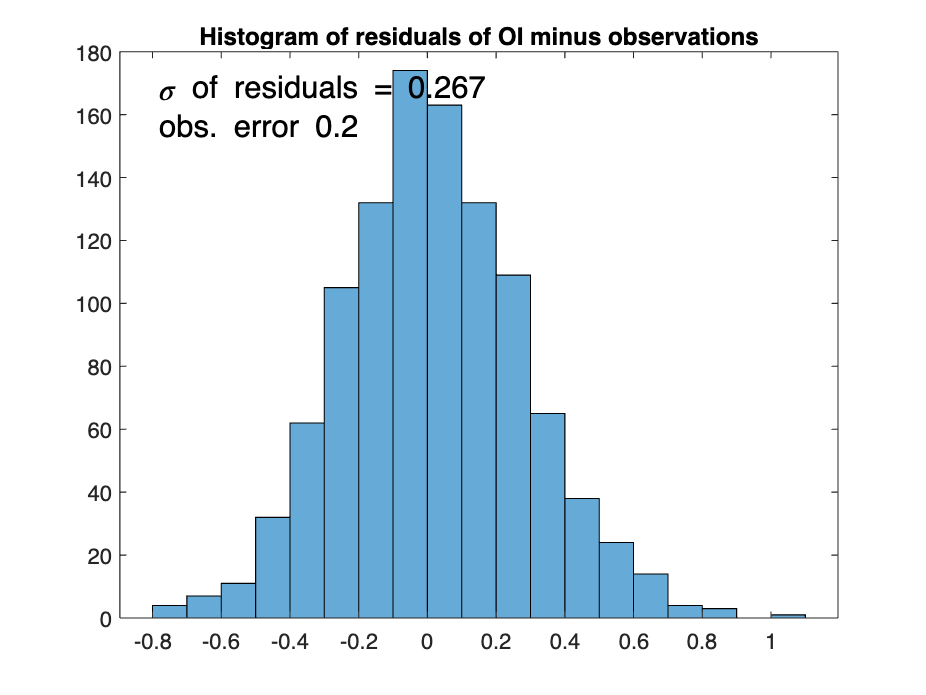

% Repeat the optimal interpolation, but map to the pseudo observation locations

% In OI, the target "model" coordinates are arbitrary and need not be on a regular
% grid. We can use the OI machinery to map the data back to the sample locations. 
% so that we can examine the residuals of the optimal interpolation fit. If OI has 
% recovered the original data well, the variance of the residuals should be close 
% to the random observation noise we added when creating the pseudo observations. 

% Mapping to the data locations is achieved by using Cdd0 in place of the Cmd 
% matrix (i.e. the 'model' grid points are now just the data coordinate 
% points). Note that we don't use Cddf because Cddf has the observation 
% error variance added to the diagonal. 
D0 = Cdd0*(Cddf\dataa);

% Plot histogram of residuals
res = D0-dataa; % both have mean(data) removed
histogram(res)
text(min(xlim)+0.05*diff(xlim),max(ylim)-0.1*diff(ylim),...
  "\sigma of residuals = "+num2str(std(res),3)+newline...
  + "obs. error "+num2str(e,3),'FontSize',14)
title("Histogram of residuals of OI minus observations")

#### Compute expected error estimate

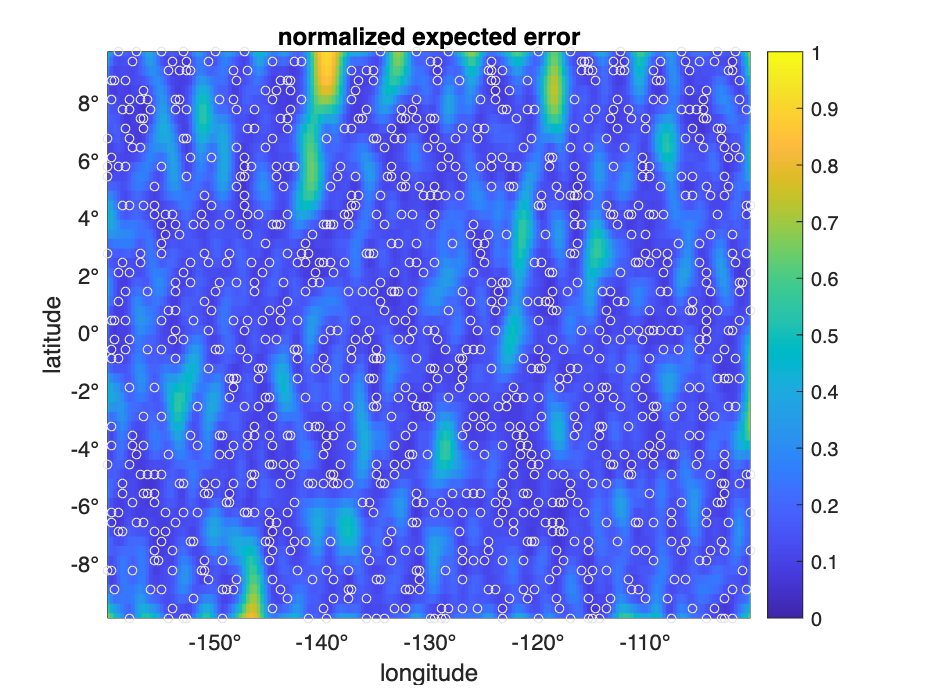

% The expected error variance of OI result is E[e^2] = s^2 - Cmd inv(Cdd) Cmd'
% We will plot this normalized by the signal variance s^2 so that the
% map shows the relative expected error. 
% 
% Where this value is near 1, the expected error is as large as the data 
% variance itself and the OI can provide no information about the solution 
% that is better than the large scale mean. This occurs when the data are 
% several covariance scales distant from the estimation point. Conversely, 
% where the data are numerous the expected error decreases. However, 
% expected error will never be less that the observation error, because 
% the OI estimate is limited by the precision of the underlying observations. 

oierrornorm = diag(1-Cmd*inv(Cddf)*Cmd');
oierrornorm = reshape(oierrornorm,size(LON));

% Plot a map of the OI error
pcolorjw(LON,LAT,oierrornorm); caxis([0 1])
colorbar
hold on
han = scatter(x,y,15,'w','o','MarkerEdgeColor','w');
han.MarkerEdgeColor = 0.9*[1 1 1];
hold off
title("normalized expected error")
xlabel('longitude');ylabel('latitude')
xtickformat('degrees');ytickformat('degrees')

#### Test how many residuals fall within the expected error estimate

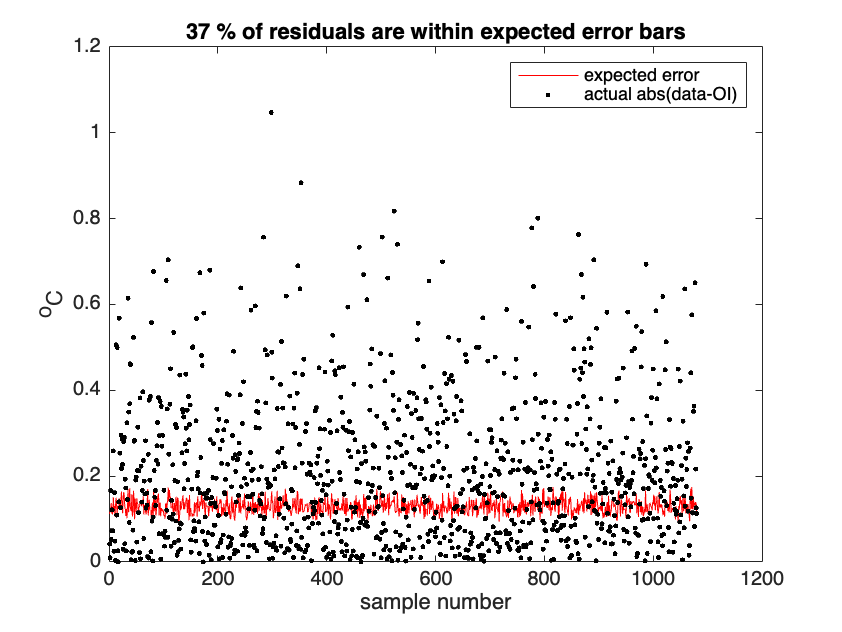

% Calculate expected error at the data locations, but this time multiply 
% by signal variance to get dimensional values (deg C^2)
oierror0 = ssq*diag(1-Cdd0*inv(Cddf)*Cdd0');

% Plot OI error in comparison to residuals
plot(1:length(dataa),sqrt(oierror0),'r-',1:length(dataa),abs(D0-dataa),'k.')
legend("expected error","actual abs(data-OI)")
within_limits = find(abs(D0-dataa)<=sqrt(oierror0));
xlabel('sample number')
ylabel('^oC')
titlestr = int2str(round(100*length(within_limits)/length(dataa)))+...
  " % of residuals are within expected error bars";
title(titlestr)

disp(titlestr+newline+" (expect 68% for normally distributed random variable)")

37 % of residuals are within expected error bars
 (expect 68% for normally distributed random variable)


drawnow

#### Further exercises

% Go back in this script and set covariance length scales that are larger, 
% or shorter, than the estimated best fit and see what happens to the quality
% of the map compared to the original "truth". 

% Go back in the script and change the density of the data subsampling, or
% the assumed observation error, and see what happens to the quality of the 
% map compared to the original "truth". 

